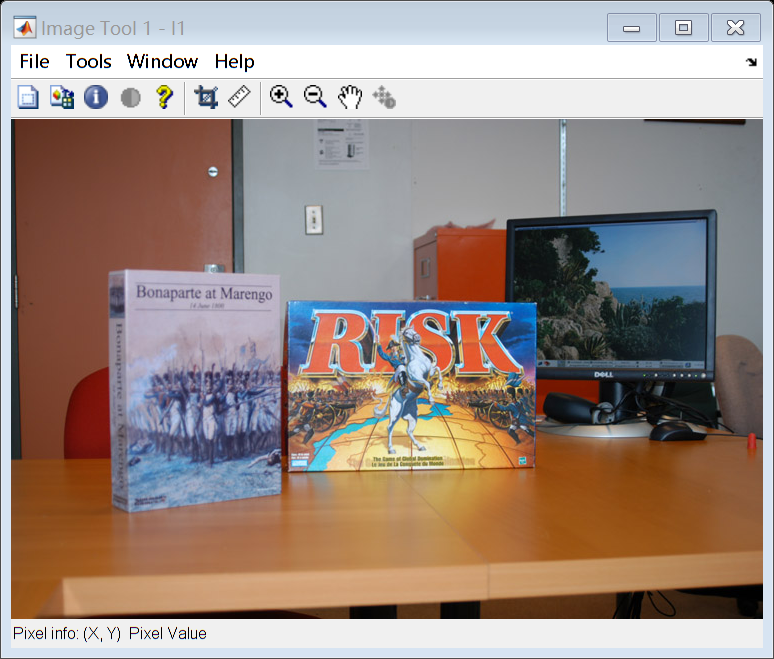

%% Image 1
I1 = imread("stereo-pairs\p11.jpg");
I2 = imread("stereo-pairs\p12.jpg");
I11 = rgb2gray(I1);
I12 = rgb2gray(I2);
imtool(I1)

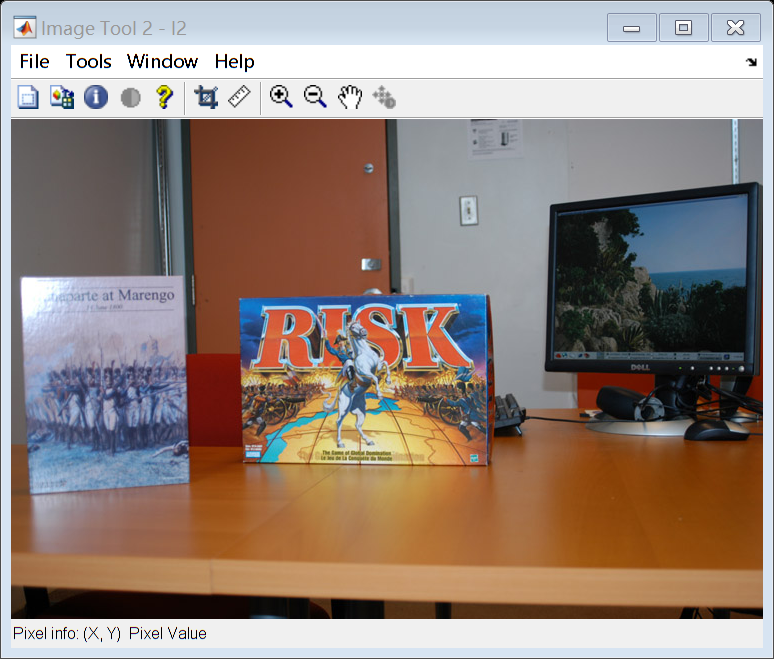

imtool(I2)

% Manually detect 8 pairs of points
% a row is [x1 y1 x2 y2]
pixel_pairs1 = [114 151 10 158;
    294 87 449 79;
    497 101 539 87;
    704 92 746 64;
    697 315 739 315;
    271 374 179 365;
    525 348 476 347;
    194 146 351 140];

F1_8point = fundamental_matrix(pixel_pairs1);
rank(F1_8point);
F1_build_in = estimateFundamentalMatrix(pixel_pairs1(:,1:2), ...
    pixel_pairs1(:,3:4),'Method',"Norm8Point");

%%
pixel_pairs2 = [360 82 348 84;
    211 325 168 325;
    282 308 256 307;
    320 390 263 389;
    393 410 281 408;
    541 294 494 295;
    139 414 63 410;
    575 380 463 381];

F2_8point = fundamental_matrix(pixel_pairs2);
rank(F2_8point);
F2_build_in = estimateFundamentalMatrix(pixel_pairs2(:,1:2), ...
    pixel_pairs2(:,3:4),'Method',"Norm8Point");
%draw_epipolar_lines(I1,I2,F1_8point,pixel_pairs1(:,1:2),pixel_pairs1(:,3:4));


Q2

[matchedLeft, matchedRight] = SurfFeaturepoints(I11,I12);
matched_list = [matchedLeft.Location matchedRight.Location];
[F1_ransac,matched_8] = ransac(matched_list,0.5,150);
F1_ransac
rank(F1_ransac);

% Draw epipolar lines
%matched1 = matched_list(inliers,1:2);
%matched2 = matched_list(inliers,3:4);
%draw_epipolar_lines(I1,I2,F1_ransac,matched_8(:,1:2),matched_8(:,3:4))


Q3

e1 = null(F1_ransac);
e1 = e1 ./ e1(3);
e2 = null(F1_ransac');
e2 = e2 ./ e2(3);

H1 = [1 0 0;
    -e1(2)/e1(1) 1 0;
    -1/e1(1) 0 1];

H2 = [1.1 0 -5;
    -e2(2)/e2(1) 1 0;
    -1/e2(1) 0 1];

I1rec = rectify(I1,H1);
I2rec = rectify(I2,H2);


points1 = rectify_points(matched_8(:,1:2),H1);
points2 = rectify_points(matched_8(:,3:4),H2);
figure;
showMatchedFeatures(I1,I2,points1,points2,'montage','PlotOptions',{'ro','go','y--'});
showMatchedFeatures(I1rec,I2rec,points1,points2,'montage','PlotOptions',{'ro','go','y--'});
title('Putative point matches');

Q4

f = 31;
sx = 31.2e-2; 
sy = 31.2e-2;
[px,py,~] = size(I11);
px = px/2;
py = py/2;
M = [f/sx 0 px;
    0 f/sy py;
    0 0 1];
E = (M')*F1_ransac*M;

function triangPoints = triang(matches,M)
    numMatches = size(matches,1);
    % homo coor
    triangPoints = zeros(4,numMatches);
    
    for i = 1:numMatches
        A = [matches(i,1).*M(3,:)-M(1,:);...
            matches(i,2).*M(3,:)-M(2,:);...
            matches(i,3).*M(3,:)-M(1,:);...
            matches(i,4).*M(3,:)-M(2,:)];
        [~,~,V] = svd(A);
        triangPoints(:,i) = V(:,end)./V(end,end);
    end
    
end

function plot_triang(triangPoints, camCenter1, camCenter2)
    figure; axis equal;  hold on; 
    plot3(-triangPoints(:,1), triangPoints(:,2), triangPoints(:,3), '.r');
    plot3(-camCenter1(1), camCenter1(2), camCenter1(3),'*g');
    plot3(-camCenter2(1), camCenter2(2), camCenter2(3),'*b');
    grid on; xlabel('x'); ylabel('y'); zlabel('z'); axis equal;
    
end


function I_rec = rectify(I,H)
    [a,b,~] = size(I);
    I_rec = zeros(a,b,3);
    for i=1:a
        for j=1:b
            new_p = H*[i;j;1];
            new_p = new_p ./ new_p(3);
            x = round(new_p(1));
            y = round(new_p(2));
            if x>0 && x<=a && y>0 && y<=b
                I_rec(x,y,:) = I(i,j,:);
            end
        end
    end
    I_rec = uint8(I_rec);
end

function [points_rect] = rectify_points(points, H)
    points_rect = zeros(size(points));

    for i = 1:size(points, 1)
        p_h = [points(i, :), 1]';
        p_rect = H * p_h;
        p_rect = p_rect ./ p_rect(3);
        points_rect(i, :) = round(p_rect(1:2)');
    end

end